 磁束密度から電流密度分布を再構成

初期設定

%%%磁石の大きさ（単位：mm ）%%%
x1=0.0;
x2=0.04;
x3=0.06;
x4=0.1;
y1=0.0;
y2=0.020;
y3=0.080;
y4=0.1;
z1=0; 
z2=0.002;
z3=0.004;   

%settings for truncation
En=0.035;
%%%分割幅 width of measurements n and how much youre making nmag%%%
n=0.002;
nmag=0.001;

%%%分割数+1%%%
nx=round((abs(x4-x1)/n)+1);
ny=round((abs(y4-y1)/n)+1);
nz=1;
nxmag=round((abs(x3-x2)/n)+1);
nymag=round((abs(y3-y2)/n)+1);
nzmag=1;

%%%直方体領域の頂点の座標%%%
Ncx=linspace(x2+nmag/2,x3+nmag/2,nxmag);      %頂点のX座標
Ncy=linspace(y2+nmag/2,y3+nmag/2,nymag);      %頂点のY座標
Ncz=[z1,z2];                 %頂点のZ座標

%%%直方体領域の頂点の中間点の座標 x,yのみ%%%
Ncxx=linspace(x1+n/2,x4-n/2,nx-1);
Ncyy=linspace(y1+n/2,y4-n/2,ny-1);
Nczz=repmat(z2,nx,ny);       
%magpart
Ncxmag=linspace(x2+nmag/2,x3-nmag/2,nxmag-1);
Ncymag=linspace(y2+nmag/2,y3-nmag/2,nymag-1);
Nczmag=repmat(z2,nxmag-1,nymag-1)

Nczmag =     0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.00


%%%各方向の測定回数%%%
Nx=nx-1;
Ny=ny-1;
Nz=1;


%Nmzのみユーザーが設定する%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%測定する範囲の(0点からの)大きさ。
% せんさの中央の座標分）で割れる大きさにする%%%%
Wnx=(x4-x1)/Nx

Wnx = 0.0020

Wny=(y4-y1)/Ny

Wny = 0.0020

Nmx=Wnx*Nx-Wnx/2;
Nmy=Wny*Ny-Wny/2;
Nmz=z2;    % Zのみ測定する座標そのものなことに注意


%%%測定点数合計%%%
Nn=Nx*Ny

Nn = 2500

%Nm is measurement area
Nm=zeros(3,Nn);
Ni=1;Nj=1;%反復計算用
for nmy=Wny/2:Wny:Nmy   %Nmに座標を入れていく計算

    for  nmx=Wnx/2:Wnx:Nmx
        Nm(:,Ni)=[nmx,nmy,Nmz];
        Ni=Ni+1;
    end
    
    Nj=Nj+1;
end
Nm

Nm =     0.0010    0.0030    0.0050    0.0070    0.0090    0.0110    0.0130    0.0150    0.0170    0.0190    0.0210    0.0230    0.0250    0.0270    0.0290    0.0310    0.0330    0.0350    0.0370    0.0390    0.0410    0.0430    0.0450    0.0470    0.0490    0.0510    0.0530    0.0550    0.0570    0.0590    0.0610    0.0630    0.0650    0.0670    0.0690    0.0710    0.0730    0.0750    0.0770    0.0790    0.0810    0.0830    0.0850    0.0870    0.0890    0.0910    0.0930    0.0950    0.0970    0.0990
    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    

磁化ベクトル推定のシミュレーション（B＝AMの順方向を行う）

Aを計算し，Mを与えてBを算出する．

%I=∭vΔ(1/r)dv とその組み合わせの行列であるAを求める%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
Nc=round((nx-1)*(ny-1))

Nc = 2500

Ncmag=round((nxmag-1)*(nymag-1))

Ncmag = 300

A=zeros(3*Nn,3*Ncmag);             %電流密度要素数
pp=0;cc=0;                      %Aに計算する時の計算用
Aa=zeros(3);   %一測定点と一要素（最終敵には合算されてAになる）
Ixx=0;Iyy=0;Izz=0;           %Iをx,y,z方向に分解したもの
Ixy=0;Iyz=0;Ixz=0; 

for cy=0:nymag-2                   %直方体頂点の座標(Ncy)の指定ny-2
    for cx=0:nxmag-2               %直方体頂点の座標(Ncx)の指定nx-2　（計算頂点の始点をずらすためのcy,cz（Zは移動しないのでいらない））
 
        pp=0;
        for p=1:Nc                 %測定点数Nn 
                for k=1:2           %頂点のz方向への移動
                    for j=1:2       %頂点のy方向への移動
                        for i=1:2   %頂点のx方向への移動

                          R=sqrt(((Nm(1,p)-Ncx(i+cx))^2)+((Nm(2,p)-Ncy(j+cy))^2)+((Nm(3,p)-Ncz(k))^2)); %直方体領域の頂点と測定点との距離
    
                          Ixxp=((-1)^(i+j+k))*(-(atan(((Nm(2,p)-Ncy(j+cy))*(Nm(3,p)-Ncz(k)))/((Nm(1,p)-Ncx(i+cx))*R))));
            
                          Ixyp=((-1)^(i+j+k))*(log(R+(Nm(3,p)-Ncz(k))));
                       
                          Ixzp=((-1)^(i+j+k))*(log(R+(Nm(2,p)-Ncy(j+cy))));
                          
                          Iyyp=((-1)^(i+j+k))*(-(atan(((Nm(1,p)-Ncx(i+cx))*(Nm(3,p)-Ncz(k)))/((Nm(2,p)-Ncy(j+cy))*R))));
                          
                          Iyzp=((-1)^(i+j+k))*(log(R+(Nm(1,p)-Ncx(i+cx))));
                          
                          Izzp=((-1)^(i+j+k))*(-(atan(((Nm(1,p)-Ncx(i+cx))*(Nm(2,p)-Ncy(j+cy)))/((Nm(3,p)-Ncz(k))*R))));
                          
                          
                          Ixx=Ixx+Ixxp;
                          Ixy=Ixy+Ixyp;
                          Ixz=Ixz+Ixzp;
                          Iyy=Iyy+Iyyp;
                          Iyz=Iyz+Iyzp;
                          Izz=Izz+Izzp;
                          
                        end
                    end
                end
                
               %NaNの対処%%%%%%%%%%%%%%%%
               if isnan(Ixx)
                     Ixxp=0;
               end      
               if isnan(Iyy)
                     Iyyp=0;
               end      
               if isnan(Izz)
                     Izzp=0;
               end
               if isnan(Ixy)
                     Ixyp=0;
               end      
               if isnan(Ixz)
                     Ixzp=0;
               end      
               if isnan(Iyz)
                     Iyzp=0;
               end

               %%%%%%%%%%%%%%%%%%%%%%%%%%%
               
               Aa=(-(1/(4*pi)))*[Ixx,Ixy,Ixz;
                               Ixy,Iyy,Iyz;
                               Ixz,Iyz,Izz];


               A(3*pp+1,3*cc+1)=Aa(1,1);
               A(3*pp+1,3*cc+2)=Aa(2,1);
               A(3*pp+1,3*cc+3)=Aa(3,1);
               
               A(3*pp+2,3*cc+1)=Aa(1,2);
               A(3*pp+2,3*cc+2)=Aa(2,2);
               A(3*pp+2,3*cc+3)=Aa(3,2);
               
               A(3*pp+3,3*cc+1)=Aa(1,3);
               A(3*pp+3,3*cc+2)=Aa(2,3);
               A(3*pp+3,3*cc+3)=Aa(3,3);
               
               Ixx=0;            %ループ毎のIの初期化
               Iyy=0;
               Izz=0;
               Ixy=0;
               Iyz=0;
               Ixz=0;
                
               pp=pp+1;
        end
         cc=cc+1;
    end
end

A

A =     0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0



% Bsim=A*Mgive

Bx=zeros(ny-1,nx-1);    
By=zeros(ny-1,nx-1);    
Bz=zeros(ny-1,nx-1);   
Babs=zeros(ny-1,nx-1);
mmx=1;mmy=1;           

% for jj=1:Nn
% 
%     if mmx < nx-1
%         Bx(mmy,mmx)=Bsim(3*(jj)-2);
%         By(mmy,mmx)=Bsim(3*(jj)-1);
%         Bz(mmy,mmx)=Bsim(3*(jj));
%         Babs(mmy,mmx)=sqrt(((Bsim(3*(jj)-2))^2)+((Bsim(3*(jj)-1))^2)+((Bsim(3*(jj))^2)));
%         mmx=mmx+1;
% 
%     elseif mmx==nx-1
%         Bx(mmy,mmx)=Bsim(3*(jj)-2);
%         By(mmy,mmx)=Bsim(3*(jj)-1);
%         Bz(mmy,mmx)=Bsim(3*(jj));
%         Babs(mmy,mmx)=sqrt(((Bsim(3*(jj)-2))^2)+((Bsim(3*(jj)-1))^2)+((Bsim(3*(jj))^2)));
%           mmx=1;
%        mmy=mmy+1;
%     end
% end
%

Ball=readmatrix("teslameter_data527.csv"); %change datasets

count=1;

for c=1:Nx
    for i=1:Ny
        Bx(i,c)=(Ball((count),2)+Ball((count+1),2)+Ball((count+2),2)+Ball((count+3),2)+Ball((count+4),2))/5;  
        By(i,c)=(Ball((count),3)+Ball((count+1),3)+Ball((count+2),3)+Ball((count+3),3)+Ball((count+4),3))/5; 
        Bz(i,c)=(Ball((count),4)+Ball((count+1),4)+Ball((count+2),4)+Ball((count+3),4)+Ball((count+4),4))/5; 
        Babs(i,c)=(Ball((count),1)+Ball((count+1),1)+Ball((count+2),1)+Ball((count+3),1)+Ball((count+4),1))/5;
        count=count+5;

    end
end
Bx

Bx =     0.0027    0.0036    0.0039    0.0045    0.0039    0.0018    0.0017    0.0017   -0.0000    0.0004    0.0006   -0.0009   -0.0006   -0.0007   -0.0025   -0.0025   -0.0017   -0.0011    0.0002    0.0015    0.0025    0.0033    0.0034    0.0029    0.0027    0.0021    0.0005    0.0006    0.0006   -0.0004   -0.0002   -0.0001   -0.0008   -0.0002    0.0001   -0.0006   -0.0001    0.0001   -0.0005   -0.0001    0.0001   -0.0005   -0.0001    0.0001   -0.0004   -0.0001    0.0001   -0.0004   -0.0000    0.0001
    0.0022    0.0031    0.0036    0.0044    0.0043    0.0026    0.0024    0.0022    0.0004    0.0008    0.0010   -0.0005   -0.0001    0.0000   -0.0018   -0.0020   -0.0016   -0.0013   -0.0003    0.0009    0.0017    0.0024    0.0029    0.0030    0.0031    0.0024    0.0008    0.0007    0.0007   -0.0004   -0.0003   -0.0003   -0.0009   -0.0003    0.0001   -0.0006   -0.0001    0.0001   -0.0006   -0.0002    0.0001   -0.0005   -0.0001    0.0001   -0.0005   -0.0001    0.0001   -0.0004   -0.0001    

By

By =    -0.0022   -0.0026   -0.0027   -0.0024   -0.0018   -0.0011   -0.0005   -0.0000    0.0003    0.0006    0.0009    0.0013    0.0020    0.0028    0.0034    0.0037    0.0036    0.0033    0.0028    0.0021    0.0014    0.0005    0.0000    0.0001    0.0005    0.0008    0.0010    0.0011    0.0012    0.0012    0.0011    0.0009    0.0007    0.0005    0.0005    0.0004    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
   -0.0016   -0.0021   -0.0025   -0.0027   -0.0024   -0.0017   -0.0009   -0.0004    0.0001    0.0004    0.0008    0.0012    0.0017    0.0024    0.0031    0.0036    0.0038    0.0036    0.0032    0.0026    0.0019    0.0010    0.0005    0.0004    0.0006    0.0010    0.0012    0.0013    0.0014    0.0013    0.0011    0.0009    0.0008    0.0006    0.0006    0.0005    0.0004    0.0004    0.0003    0.0002    0.0002    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    

Bz

Bz =     0.0054    0.0037    0.0029    0.0006   -0.0037   -0.0019   -0.0002   -0.0031   -0.0006    0.0008   -0.0021   -0.0000    0.0012   -0.0013    0.0014    0.0049    0.0058    0.0073    0.0084    0.0081    0.0074    0.0060    0.0042    0.0037    0.0029    0.0009    0.0025    0.0032    0.0013    0.0025    0.0030    0.0014    0.0029    0.0032    0.0011    0.0022    0.0025    0.0007    0.0017    0.0021    0.0004    0.0014    0.0017    0.0001    0.0012    0.0014   -0.0000    0.0009    0.0012   -0.0001
    0.0058    0.0047    0.0042    0.0024   -0.0018   -0.0012   -0.0001   -0.0030   -0.0006    0.0009   -0.0019    0.0003    0.0015   -0.0014    0.0006    0.0035    0.0042    0.0060    0.0075    0.0075    0.0075    0.0072    0.0062    0.0055    0.0041    0.0017    0.0031    0.0038    0.0018    0.0028    0.0034    0.0018    0.0033    0.0036    0.0015    0.0025    0.0028    0.0009    0.0019    0.0023    0.0005    0.0015    0.0018    0.0002    0.0012    0.0015    0.0000    0.0009    0.0013   -

Babs

Babs =     0.0064    0.0058    0.0056    0.0051    0.0057    0.0029    0.0018    0.0035    0.0007    0.0011    0.0024    0.0016    0.0024    0.0032    0.0045    0.0066    0.0070    0.0081    0.0089    0.0085    0.0079    0.0069    0.0054    0.0047    0.0040    0.0024    0.0027    0.0034    0.0019    0.0028    0.0032    0.0016    0.0031    0.0033    0.0012    0.0023    0.0025    0.0007    0.0018    0.0022    0.0004    0.0015    0.0017    0.0002    0.0012    0.0014    0.0002    0.0010    0.0012    0.0002
    0.0064    0.0060    0.0060    0.0057    0.0052    0.0034    0.0026    0.0037    0.0007    0.0013    0.0023    0.0013    0.0023    0.0028    0.0036    0.0054    0.0059    0.0072    0.0082    0.0080    0.0079    0.0077    0.0068    0.0063    0.0052    0.0031    0.0034    0.0041    0.0023    0.0031    0.0036    0.0021    0.0035    0.0037    0.0016    0.0026    0.0028    0.0009    0.0020    0.0023    0.0006    0.0016    0.0018    0.0003    0.0013    0.0015    0.0002    0.0010    0.0013  

算出したBを表示する

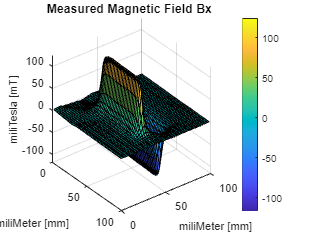


%Bxの表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%3D分布

surf(Ncxx*1000,Ncyy*1000,Bx*1000)
set(gca,'YDir','reverse')   %Y軸方向反転処理
% xlim([0 Nx+1])
% ylim([0 Ny+1])
b=(["Measured Magnetic Field Bx "]);
title(b)
zlabel('miliTesla [mT]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

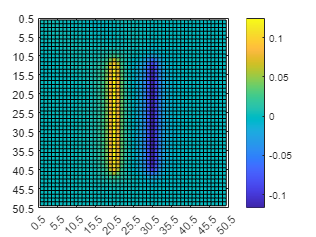


%2D分布
surf(Bx)
set(gca,'YDir','reverse')
axis equal
grid off
box on
xlim([0.5 Nx+0.5])
ylim([0.5 Ny+0.5])
xticks(0.5:5:Nx+1)
yticks(0.5:5:Ny+1)
view([0 90.0])
colorbar

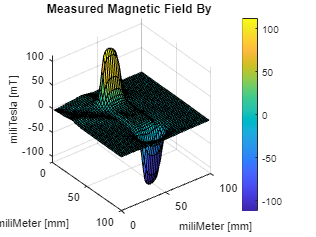


%Byの表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%3D分布
surf(Ncxx*1000,Ncyy*1000,By*1000)
set(gca,'YDir','reverse')
b=(["Measured Magnetic Field By "]);
title(b)
zlabel('miliTesla [mT]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

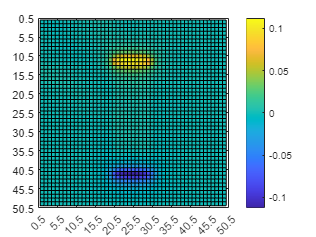


%2D分布
surf(By)
set(gca,'YDir','reverse')
colorbar
axis equal
grid off
box on
xlim([0.5 Nx+0.5])
ylim([0.5 Ny+0.5])
xticks(0.5:5:Nx+1)
yticks(0.5:5:Ny+1)
view([0 90.0])

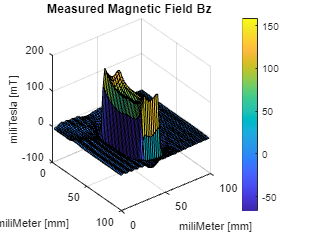


%Bzの表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%3D分布
surf(Ncxx*1000,Ncyy*1000,-Bz*1000)
set(gca,'YDir','reverse')
b=(["Measured Magnetic Field Bz "]);
title(b)
zlabel('miliTesla [mT]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

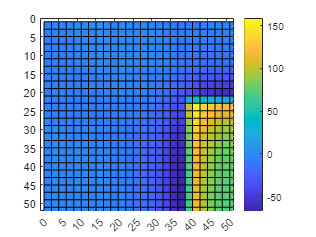


%2D分布
surf(Ncxx*1000,Ncyy*1000,-Bz*1000)
set(gca,'YDir','reverse')
colorbar
axis equal
grid off
box on
xlim([0 Nx+2])
ylim([0 Ny+2])
xticks(0:5:Nx+1)
yticks(0:5:Ny+1)
view([0 90.0])

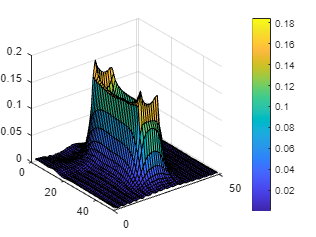


%Babsの表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%3D分布
surf(Babs)
set(gca,'YDir','reverse')
xlim([0 Nx+1])
ylim([0 Ny+1])
colorbar

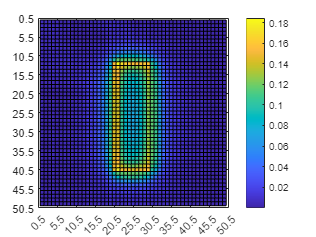


%2D分布
surf(Babs)
set(gca,'YDir','reverse')
colorbar
axis equal
grid off
box on
xlim([0.5 Nx+0.5])
ylim([0.5 Ny+0.5])
xticks(0.5:5:Nx+1)
yticks(0.5:5:Ny+1)
view([0 90.0])


%取り込んだBをひとまとめにするループ計算(Bymを無視するときはif文中のその部分(77,82行目)をコメント化すればOk)%%%%%%%%%%%%%%%%%%%%%%%%%
Bm=zeros(Nn*3,1);
bnx=1;bny=1;   %計算用変数

for bn=1:Nn      
    if bnx < Nx
           Bm(3*(bn)-2)=Bx(bny,bnx);
           Bm(3*(bn)-1)=By(bny,bnx);
           Bm(3*(bn))=Bz(bny,bnx);
        bnx=bnx+1;
    elseif bnx==Nx
           Bm(3*(bn)-2)=Bx(bny,bnx);
           Bm(3*(bn)-1)=By(bny,bnx);
           Bm(3*(bn))=Bz(bny,bnx);
          bnx=1;
       bny=bny+1;
    end

end
Bm

Bm =     0.0027
   -0.0022
    0.0054
    0.0036
   -0.0026
    0.0037
    0.0039
   -0.0027
    0.0029
    0.0045


打ち切り特異値分解を用いてAの擬似逆行列求める（設定する値）

計算部分

[U,S,V] = svd(A)            %特異値分解

U =    -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0

S =     0.6807         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.6807         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0001   -0.0000    0.0002   -0.0001    0.0000   -0.0000    0.0006   -0.0003    0.0013   -0.0005    0.0002   -0.0021    0.0018   -0.0004    0.0001    0.0049   -0.0005   -0.0019    0.0014    0.0051   -0.0060    0.0011    0.0008   -0.0111    0.0037    0.0005    0.0029    0.0151   -0.0013    0.0093   -0.0024    0.0026   -0.0007    0.0184   -0.0036    0.0054   -0.0057    0.0093   -0.0029    0.0143   -0.0182    0.0046   -0.0019
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0001   -0.0001   -0.0002    0.0002   -0.0002    0.0001   -0.0000    0.0007   -0.0007    0.0013   -0.0005    0.0003   -0.0028    0.0010   -0.0004    0.0002    0.0047    0.0019   -0.0010    0.0025    0.0012   -0.0080    0.0011    0.0002   -0.0114   -0.0033    0.0020    0.0026    0.0115   -0.0099    0.0090    0.0040    0.0021    0.0009    0.0170    0.0087    0.0011   -0.0077    0.0112    0.0008    0.0220   -0.0044    0.0006   -0

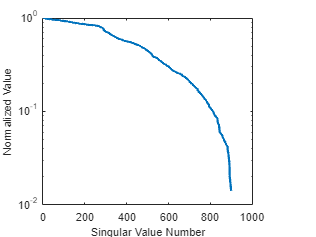

Ut=U';                      %Uの転置行列
invA1=zeros(size(S'));      %最終的な擬似逆行列
invAa=zeros(size(S'));      %1モード（1特異値）あたりの逆行列
M1=invA1*Bm;                %打ち切り判定用推定電流密度分布
adnum=0;                    %加算回数

S1=diag(S);
Snor=S1/max(S1);
p1=1:3*Ncmag;
ln=semilogy(p1,Snor,'LineWidth',2);
ax1=gca;
ax1.YAxis.Exponent = 0;
ax1.YAxis.TickLabelFormat = '%.0f';
xlabel('Singular Value Number', 'FontSize',10) 
ylabel('Normalized Value', 'FontSize',10)





% Snor1=Snor(1:Nn*3,1);
% p2=1:Nn*3;
% ln=semilogy(p2,Snor1,'LineWidth',2);
%}
%逆行列を求めて加算invA=Σv*ut/λ
xx=1;
for aa=1:3*Ncmag
    
    invAa=(V(:,aa)*Ut(aa,:))/S(aa,aa);  %v*ut/λ
    M1=invA1*Bm;
    Smud=Snor(aa,:);%打ち切りの判定%%%%%%%%%%%%%%%%%%%%%%%  
    sss(xx)=Smud;
    xx=xx+1;
        if  Smud>=En%正規化した特異値を参照した打ち切り判定
           
            invA1=invA1+invAa;            %加算していく
            adnum=adnum+1;                %加算回数も増加

        else 
           break
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

%計算結果確認用
invA1

invA1 =     0.0004    0.0002    0.0001    0.0005    0.0003    0.0001    0.0005    0.0003    0.0001    0.0006    0.0004    0.0001    0.0006    0.0004    0.0001    0.0007    0.0005    0.0001    0.0008    0.0006    0.0002    0.0009    0.0008    0.0002    0.0009    0.0009    0.0002    0.0010    0.0011    0.0002    0.0011    0.0013    0.0002    0.0011    0.0016    0.0002    0.0011    0.0019    0.0002    0.0011    0.0023    0.0003    0.0010    0.0026    0.0003    0.0008    0.0030    0.0003    0.0005    0.0034
    0.0007    0.0001    0.0001    0.0007    0.0002    0.0001    0.0008    0.0002    0.0001    0.0009    0.0003    0.0001    0.0010    0.0004    0.0001    0.0011    0.0004    0.0001    0.0012    0.0006    0.0001    0.0014    0.0007    0.0001    0.0015    0.0009    0.0001    0.0016    0.0011    0.0001    0.0018    0.0014    0.0001    0.0019    0.0017    0.0001    0.0020    0.0021    0.0001    0.0020    0.0025    0.0001    0.0020    0.0030    0.0001    0.0019    0.0035    0.0001    0.0016 

adnum

adnum = 886



%電流密度分布を逆計算

M=invA1*Bm

M =     0.0665
   -0.1964
   -0.2988
    0.0890
   -0.0405
   -0.3660
    0.0550
   -0.0194
   -0.4021
    0.0072


MをMx,My,Mzの分布に変換（特に設定する値なし）

Mx=zeros(nymag-1,nxmag-1);    %x方向電流密度
My=zeros(nymag-1,nxmag-1);    %y方向
Mz=zeros(nymag-1,nxmag-1);    %z方向
Mabs=zeros(nymag-1,nxmag-1);  %大きさ
mmx=1;mmy=1;            %計算用変数


for jj=1:Ncmag

    if mmx < nxmag-1
        Mx(mmy,mmx)=M(3*(jj)-2);
        My(mmy,mmx)=M(3*(jj)-1);
        Mz(mmy,mmx)=M(3*(jj));
        Mabs(mmy,mmx)=sqrt(((M(3*(jj)-2))^2)+((M(3*(jj)-1))^2)+((M(3*(jj))^2)));
        mmx=mmx+1;
        
    elseif mmx==nxmag-1
        Mx(mmy,mmx)=M(3*(jj)-2);
        My(mmy,mmx)=M(3*(jj)-1);
        Mz(mmy,mmx)=M(3*(jj));
        Mabs(mmy,mmx)=sqrt(((M(3*(jj)-2))^2)+((M(3*(jj)-1))^2)+((M(3*(jj))^2)));
          mmx=1;
       mmy=mmy+1;
    end
end

Mx

Mx =     0.0665    0.0890    0.0550    0.0072   -0.0409   -0.0704   -0.0872   -0.0910   -0.0713   -0.0413
    0.3887    0.4315    0.3909    0.3001    0.2041    0.1231    0.0590    0.0098   -0.0214   -0.0567
    0.3787    0.4636    0.4336    0.3456    0.2395    0.1449    0.0648    0.0014   -0.0375   -0.0715
    0.3807    0.4640    0.4474    0.3657    0.2610    0.1617    0.0763    0.0067   -0.0373   -0.0757
    0.3669    0.4538    0.4404    0.3666    0.2672    0.1694    0.0834    0.0131   -0.0331   -0.0743
    0.3584    0.4424    0.4312    0.3626    0.2691    0.1740    0.0897    0.0216   -0.0256   -0.0711
    0.3500    0.4317    0.4197    0.3552    0.2670    0.1751    0.0944    0.0288   -0.0181   -0.0677
    0.3423    0.4214    0.4075    0.3463    0.2621    0.1749    0.0976    0.0353   -0.0118   -0.0648
    0.3364    0.4128    0.3968    0.3364    0.2569    0.1741    0.0985    0.0403   -0.0063   -0.0622
    0.3315    0.4053    0.3871    0.3290    0.2535    0.1717    0.1000    0.0452   -0.

My

My =    -0.1964   -0.0405   -0.0194    0.0072    0.0059    0.0132    0.0259    0.0211    0.0183   -0.1019
   -0.2576   -0.1141   -0.0290    0.0121    0.0074    0.0195    0.0519    0.0407    0.0124   -0.2114
   -0.3397   -0.2129   -0.0922   -0.0315   -0.0463   -0.0293    0.0225    0.0066   -0.0561   -0.3001
   -0.3619   -0.2873   -0.1355   -0.0663   -0.0916   -0.0748   -0.0060   -0.0278   -0.1319   -0.3616
   -0.3651   -0.3301   -0.1616   -0.0869   -0.1237   -0.1097   -0.0295   -0.0567   -0.2003   -0.3968
   -0.3630   -0.3563   -0.1753   -0.0987   -0.1453   -0.1360   -0.0493   -0.0811   -0.2580   -0.4138
   -0.3634   -0.3719   -0.1833   -0.1055   -0.1596   -0.1552   -0.0656   -0.1026   -0.3044   -0.4188
   -0.3687   -0.3815   -0.1900   -0.1115   -0.1698   -0.1682   -0.0808   -0.1212   -0.3396   -0.4166
   -0.3782   -0.3874   -0.1974   -0.1201   -0.1767   -0.1774   -0.0970   -0.1377   -0.3632   -0.4106
   -0.3913   -0.3905   -0.2086   -0.1314   -0.1818   -0.1866   -0.1138   -0.1545   -0.

Mz

Mz =    -0.2988   -0.3660   -0.4021   -0.4094   -0.4040   -0.3859   -0.3589   -0.3349   -0.2932   -0.1580
   -0.4554   -0.7047   -0.8053   -0.8484   -0.8577   -0.8395   -0.7970   -0.7511   -0.6673   -0.3255
   -0.4552   -0.7608   -0.9239   -1.0052   -1.0383   -1.0322   -0.9877   -0.9275   -0.8153   -0.3900
   -0.4295   -0.7483   -0.9387   -1.0489   -1.1009   -1.1077   -1.0688   -1.0014   -0.8715   -0.4098
   -0.4169   -0.7274   -0.9291   -1.0522   -1.1172   -1.1339   -1.1023   -1.0326   -0.8917   -0.4133
   -0.4122   -0.7131   -0.9159   -1.0440   -1.1149   -1.1377   -1.1112   -1.0435   -0.8966   -0.4117
   -0.4128   -0.7056   -0.9065   -1.0334   -1.1063   -1.1317   -1.1112   -1.0433   -0.8939   -0.4087
   -0.4146   -0.7025   -0.9011   -1.0245   -1.0953   -1.1242   -1.1070   -1.0386   -0.8869   -0.4058
   -0.4160   -0.7008   -0.8994   -1.0170   -1.0856   -1.1176   -1.1001   -1.0329   -0.8792   -0.4032
   -0.4169   -0.6988   -0.8968   -1.0128   -1.0812   -1.1094   -1.0937   -1.0274   -0.

Mabs

Mabs =     0.3637    0.3789    0.4064    0.4095    0.4061    0.3925    0.3703    0.3477    0.3023    0.1925
    0.6518    0.8341    0.8956    0.9000    0.8817    0.8487    0.8009    0.7522    0.6678    0.3923
    0.6827    0.9160    1.0247    1.0635    1.0666    1.0427    0.9901    0.9275    0.8181    0.4973
    0.6785    0.9262    1.0487    1.1128    1.1351    1.1219    1.0715    1.0018    0.8822    0.5517
    0.6646    0.9187    1.0408    1.1177    1.1553    1.1518    1.1058    1.0343    0.9145    0.5778
    0.6558    0.9117    1.0274    1.1095    1.1561    1.1589    1.1159    1.0469    0.9334    0.5880
    0.6519    0.9069    1.0156    1.0979    1.1492    1.1557    1.1171    1.0487    0.9445    0.5891
    0.6519    0.9037    1.0071    1.0872    1.1390    1.1501    1.1142    1.0462    0.9497    0.5852
    0.6551    0.9009    1.0026    1.0779    1.1295    1.1450    1.1087    1.0428    0.9513    0.5788
    0.6609    0.8973    0.9988    1.0729    1.1253    1.1380    1.1041    1.0399    

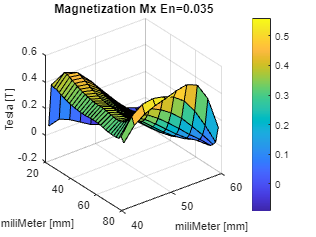

%結果のグラフ表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


surf(Ncxmag*1000,Ncymag*1000,Mx)
set(gca,'YDir','reverse')
b=(["Magnetization Mx En="+En]);
%b=(["Magnetization Mx Control"]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

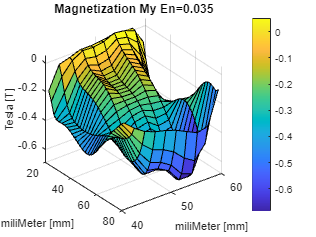



surf(Ncxmag*1000,Ncymag*1000,My)
set(gca,'YDir','reverse')
b=(["Magnetization My En="+En]);
%b=(["Magnetization My Control"]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

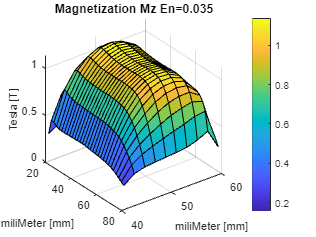



surf(Ncxmag*1000,Ncymag*1000,-Mz)
set(gca,'YDir','reverse')
b=(["Magnetization Mz En="+En]);
%b=(["Magnetization Mz Control"]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

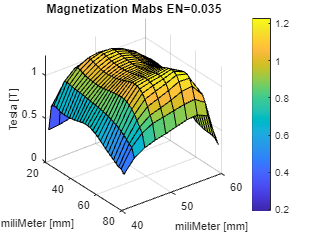



surf(Ncxmag*1000,Ncymag*1000,Mabs)
set(gca,'YDir','reverse')
b=(["Magnetization Mabs EN="+En]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

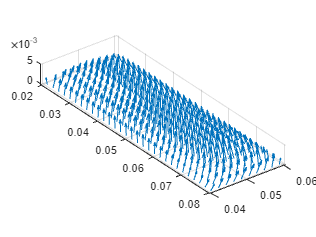


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%磁化ベクトル分布のグラフ表示%%%%%%%%%%%%%

%MMx=abs(Mx);
%MMy=abs(My);
%MMz=abs(Mz);
%MMabs=abs(Mabs);

%Mx%%%%%%%%%%%%%%%%%%

%z方向成分(Mz)の2次元ベクトル
% quiver3(Ncxmag,Ncymag,zeros(size(Ncymag,2),size(Ncxmag,2)),zeros(size(Ncymag,2),size(Ncxmag,2)),zeros(size(Ncymag,2),size(Ncxmag,2)),-Mz,5)
quiver3(Ncxmag,Ncymag,zeros(size(Ncymag,2),size(Ncxmag,2)),Mx,My,-Mz,2)
set(gca,'YDir','reverse')
axis equal
xlim([min(Ncxmag)-Wnx/2 max(Ncxmag)+Wnx/2])
ylim([min(Ncymag)-Wny/2 max(Ncymag)+Wny/2])

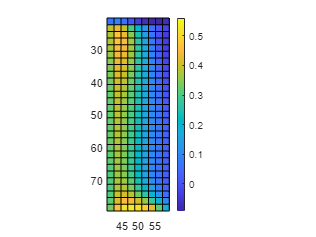

% xticks(Wnx*2:max(Ncxmag)+Wnx)
% yticks(Wny*2:max(Ncymag)+Wny)


surf(Ncxmag*1000,Ncymag*1000,Mx)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])

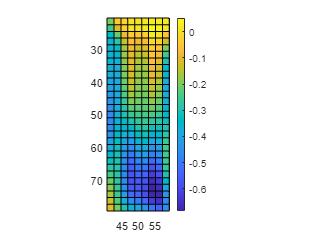



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
%My%%%%%%%%%%%%%%%%%%

surf(Ncxmag*1000,Ncymag*1000,My)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])

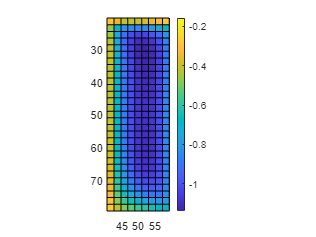


%Mz%%%%%%%%%%%%%%%%%%

surf(Ncxmag*1000,Ncymag*1000,Mz)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])

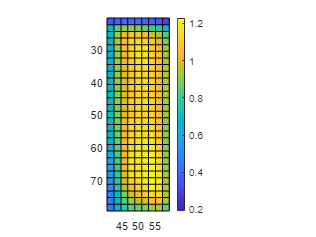




%Mabs%%%%%%%%%%%%%%%%%%
surf(Ncxmag*1000,Ncymag*1000,Mabs)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])